#### **Drawing Ellipses**

In this project, I created a custom function to generate and visualize an ellipse. This approach allowed me to define the ellipse’s major and minor axes, as well as its center, giving me full control over its shape and position.

The function, `getEllipse`, generates the coordinates of the ellipse by using parametric equations. I started by defining evenly spaced angle values between 0 and 2π2\pi2π. The x- and y-coordinates of the ellipse were calculated using cosine and sine functions, scaled by the lengths of the major and minor axes. To position the ellipse correctly, I adjusted the coordinates based on its specified center.

For this example, I set the major axis to 3, the minor axis to 1, and the center at [2,3][2, 3][2,3]. Using the generated coordinates, I plotted the ellipse in green and ensured the axes were equally scaled to maintain its true shape. The result was a smooth and well-defined ellipse that visually reflected the specified parameters.

This project demonstrated the flexibility of parametric equations for creating custom shapes

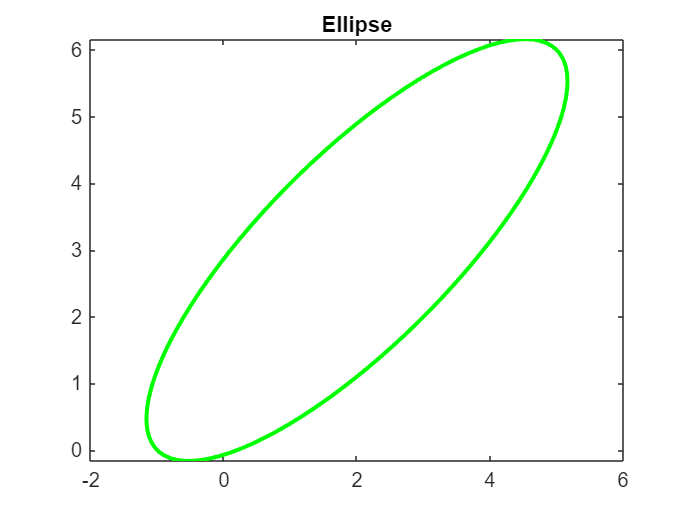

% Function to Generate Ellipse Points
function [x, y] = getEllipse(r1, r2, C)
    % I created a function to generate ellipse points for plotting.
    beta = linspace(0, 2 * pi, 100); % Angle values
    x = r1 * cos(beta) - r2 * sin(beta); % x-coordinates
    y = r1 * cos(beta) + r2 * sin(beta); % y-coordinates
    x = x + C(1); % Adjust for center x
    y = y + C(2); % Adjust for center y
end

% Plotting an Ellipse
% I want to draw an ellipse using the defined function.

% Define parameters for the ellipse
r1 = 3; % Major axis
r2 = 1; % Minor axis
C = [2, 3]; % Center of the ellipse [x, y]

% Get the ellipse points
[x, y] = getEllipse(r1, r2, C);

% Plot the ellipse
figure;
plot(x, y, 'g', 'LineWidth', 2);
axis equal;
title('Ellipse');